# 2024 Sports Biomechanics, Week 2　

## 関節角度計算

モーションキャプチャーにより、マーカー位置の3次元データが得られた。

関節角度（ユークリッド角）を計算してみよう。

## １．データを読み込む

clear
close all
clc

% load 
fileName = 'DemoDataSJ' ;
load(fileName) ;



## **２．関節角度を計算する**

例えば、膝関節は、股関節・膝関節・足関節の3点で定義されるユークリッド角として計算できる

余弦定理、あるいは、ベクトルの内積の公式を思い出そう


$$\overrightarrow{a} \cdot \overrightarrow{\;b} =|\overrightarrow{\;a|} |\overrightarrow{\;b} |\mathrm{cos}\left(\theta \right)$$



$$\mathrm{cos}\left(\theta \right)=\frac{\;\overrightarrow{a} \cdot \overrightarrow{\;b} }{|\overrightarrow{\;a|} |\overrightarrow{\;b} |}$$


MATLABで成分ごとの演算を行うには、ドットを用いる　（例：　a.*b, a.^2 

単に　a*b, a^2 　と書くと、行列として演算する（しようとしてサイズ不一致のエラーが出る）ので注意

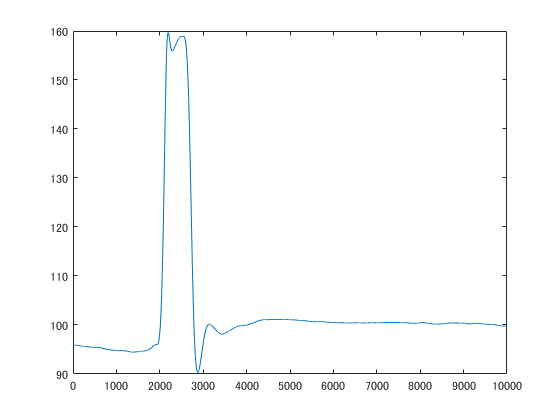


% 膝関節角度
vecA = Markers.Gt - Markers.Knee ;
vecB = Markers.Ankle - Markers.Knee ;

productAB = sum(vecA.*vecB,2) ;
absA = sum(vecA.^2,2).^0.5 ;
absB = sum(vecB.^2,2).^0.5 ;

cosTheta = productAB ./ (absA .* absB) ;
kneeAngDeg = acosd(cosTheta) ;

plot(kneeAngDeg)

## ５．プロット

いろいろ応用が効くようになると、分かりやすい図、が作れるようになります

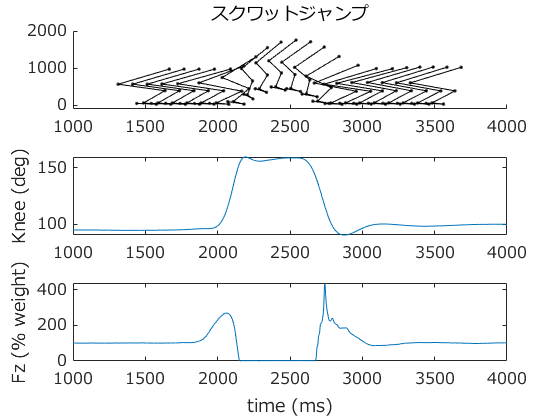

figure;
xlim = [1000,4000] ;

subplot(3,1,1) ; hold on
MarkerFieldNames = fieldnames(Markers) ;
Markers2 = Markers ;
for iFrame = [1500:100:3500] % 繰り返し実行のプログラミング：　for loop
    for iMarker = 1:length(MarkerFieldNames)
        Markers2.(MarkerFieldNames{iMarker})(:,2) = Markers.(MarkerFieldNames{iMarker})(:,2) - 150 + iFrame ;
    end
    stickPicture(Markers2, MarkerFieldNames, iFrame, 'yz', 'k.-') ; 
end
set(gca, 'xlim', xlim, 'ylim', [-100, 2000])
title('スクワットジャンプ')
set(gca, 'fontsize', 12, 'fontname', 'meiryo')
% set(gca, 'xtick', [])

subplot(3,1,2) ;
plot(kneeAngDeg) ;
set(gca, 'xlim', xlim)
ylabel('Knee (deg)')
set(gca, 'fontsize', 12, 'fontname', 'meiryo')

subplot(3,1,3) ;
fzL = grfs(:,3) ; % 3列目は、左足が受けた床反力
fzR = grfs(:,6) ; % 6列目は、右足が受けた床反力
fz = fzL + fzR ;  % 左右の床反力を足して、身体が地面から受けた床反力
fzPerWeight = fz * 100 ;
plot(fzPerWeight)
ylabel('Fz (% weight)')
xlabel('time (ms)')
set(gca, 'fontsize', 12, 'fontname', 'meiryo')
set(gca, 'xlim', xlim)